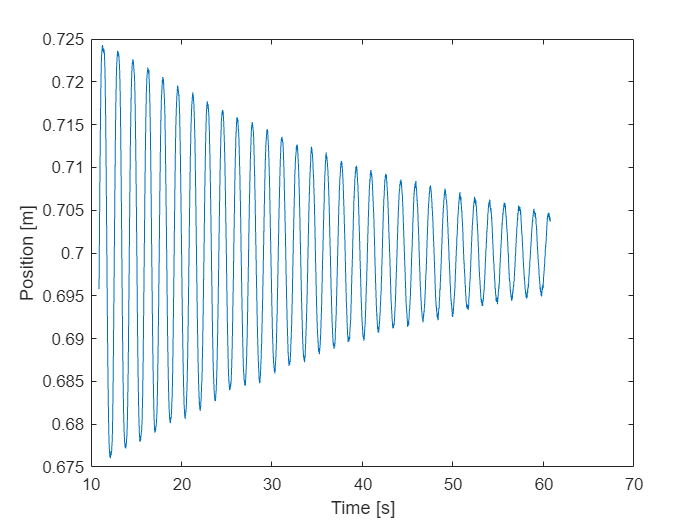

clc; clear; close all;
load test_trj1_copy_NO_SHAPER.mat
Tc= 0.001; %s
tempo_inizio = 10.890;%s
%Per scartare dati rumorosi
indice_inizio = tempo_inizio* 1/Tc;
time = time(indice_inizio:end);
joint_position = joint_position(indice_inizio:end);
plot(time, joint_position)
xlabel("Time [s]")
ylabel("Position [m]")

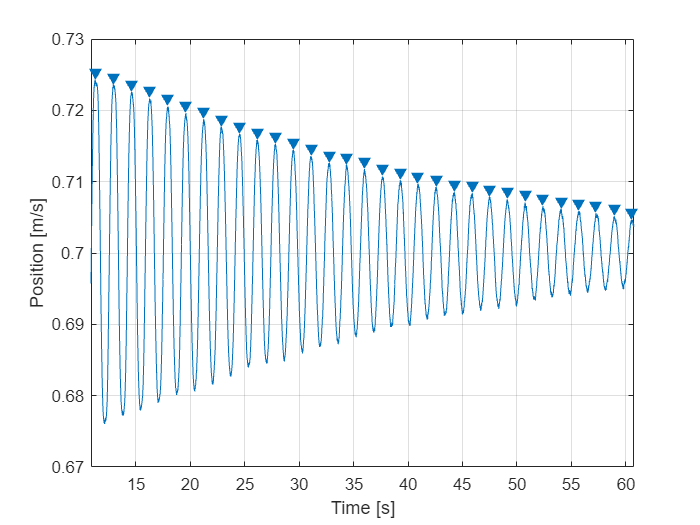

[pks,locs] = findpeaks(joint_position,time, MinPeakDistance=1);
findpeaks(joint_position,time, MinPeakDistance=1)
xlabel("Time [s]")
ylabel("Position [m/s]")

xi = 1/sqrt( 1+( (2*pi) / (log (pks(1)/pks(2)) ))^2)

xi = 1.5133e-04

delta = log (pks(1)/pks(2))

delta = 9.5086e-04

xi = 2*delta*sqrt(1/4 * delta^2 + pi^2)/(delta^2+4*pi^2)

xi = 1.5133e-04

omega_d = 2*pi/(locs(2)-locs(1))

omega_d = 3.6982


res = [];
for i=1:length(locs)-1
    res = [res;2*pi/(locs(i+1)-locs(i))];

end
omega_d=mean(res)

omega_d = 3.8251

res = [];
for i=1:length(locs)-1
    res = [res;1/sqrt( 1+( (2*pi) / (log (locs(i)/locs(i+1)) ))^2)];

end
xi = mean(res)

xi = 0.0089